# **Esercitazione 3 - EMG**

8 prove in 4 condizioni diverse.

Condizione 1 (prove 1 e 2): i soggetti dovevano compiere movimenti piccoli e lenti.

Condizione 2 (prove 3 e 4): movimenti piccoli e veloci.

Condizione 3 (prove 5 e 6): movimenti grandi e lenti.

Condizione 4 (prove 7 e 8): movimenti grandi e veloci.

load("emg_data.mat")

*Obiettivo 1: Estrarre l’inviluppo del segnale EMG per ogni soggetto per ogni prova. *

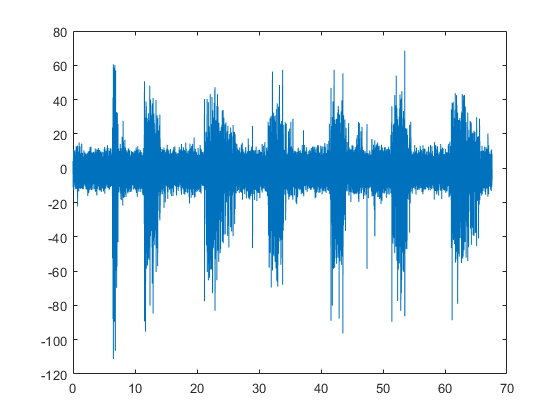

%uso della funzione get_envelope() 

fs = 2000;
nfft= 1024;

signal = cell2mat(emg_data(1));

%
figure
plot(signal(:,1), signal(:,2))

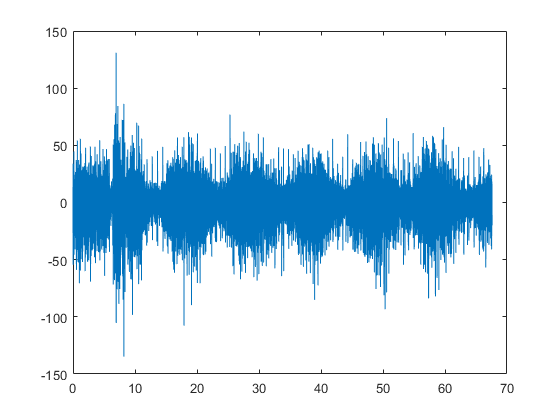

figure
plot(signal(:,1), signal(:,3))

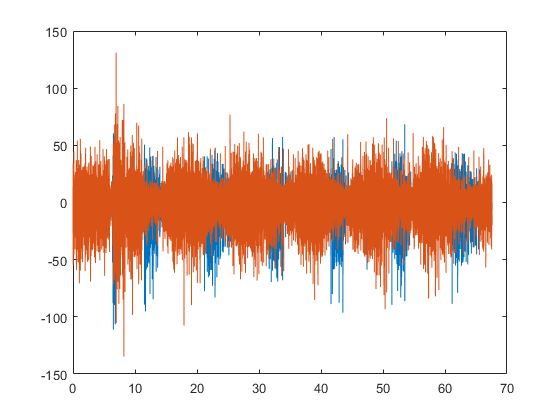

figure
plot(signal(:,1), signal(:,2)), hold on, plot(signal(:,1),signal(:,3))

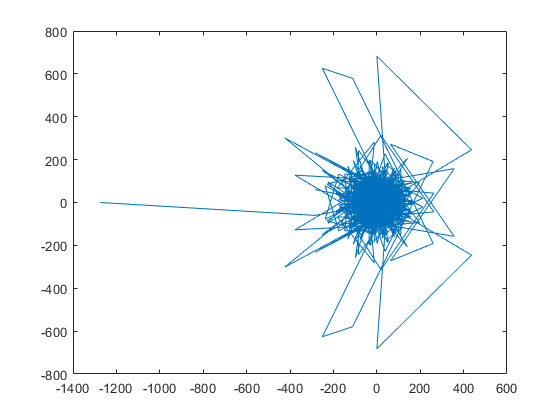


%primo muscolo
yF1= fft (signal(:,2), nfft);

figure, plot(yF1)

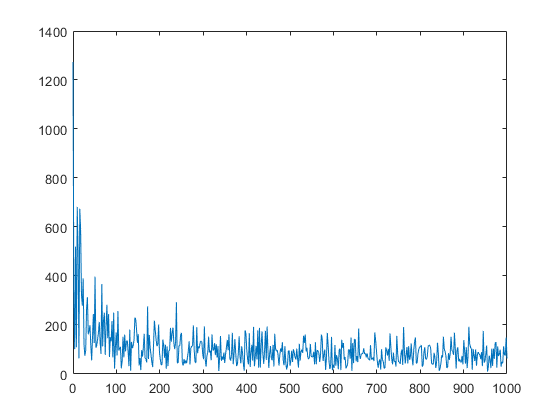

f=linspace(0, fs/2, floor(nfft/2)+1);

figure 
plot(f,abs(yF1(1:floor(nfft/2)+1)))


[~, iF] = max(abs(yF1(1:floor(nfft/2)+1)));
% f_peak = f (iF)
% 
% Wn= [1, f_peak + 20] / (fs/2) 
Wn= [30, 40] / (fs/2)

Wn =     0.0300    0.0400


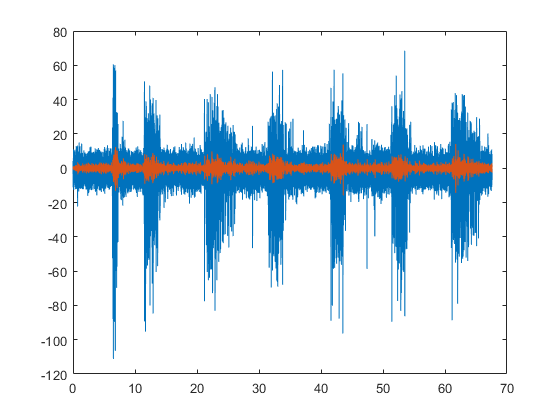


[b,a] = fir1(200,Wn);

sig_filtered = filter(b, a, signal(:,2));
figure, plot(signal(:,1),signal(:,2)), hold on, plot(signal(:,1), sig_filtered);

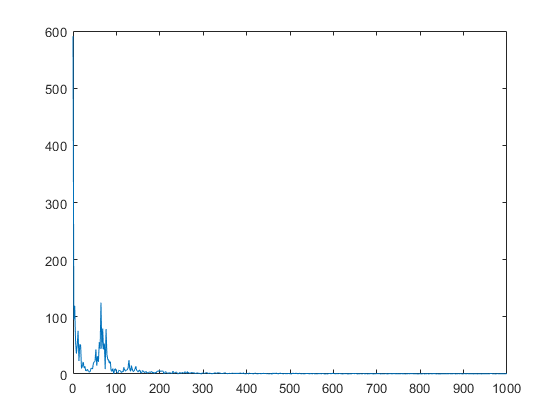


%segnale raddrizzato
sig_rect = abs(sig_filtered);

yff= fft(sig_rect,nfft);
figure, plot(f,abs(yff(1:floor(nfft/2)+1)))

Wn2 = [500 900] / (fs/2)

Wn2 =     0.5000    0.9000


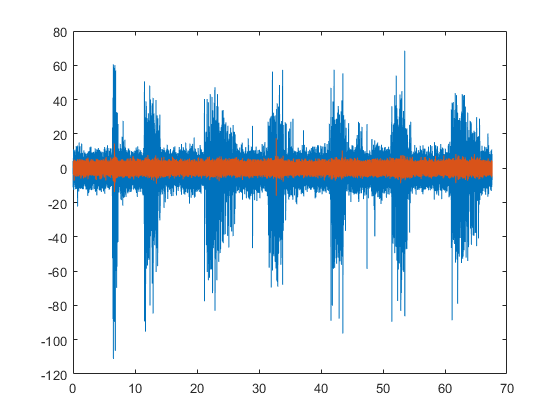

[b,a] = fir1(200,Wn2);

sig_filtered_r = filter(b, a, signal(:,2));
figure, plot(signal(:,1),signal(:,2)), hold on, plot(signal(:,1), sig_filtered_r);

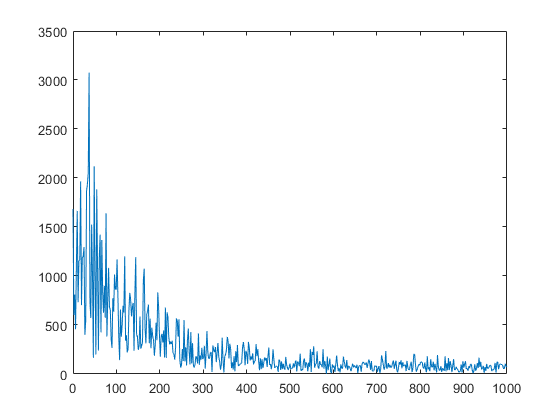


%secondo muscolo

yF= fft (signal(:,3), nfft);
f=linspace(0, fs/2, floor(nfft/2)+1);

figure 
plot(f,abs(yF(1:floor(nfft/2)+1)))


[~, iF] = max(abs(yF(1:floor(nfft/2)+1)));
f_peak = f (iF)

f_peak = 37.1094


Wn= [f_peak - 5, f_peak + 5] / (fs/2) 

Wn =     0.0321    0.0421


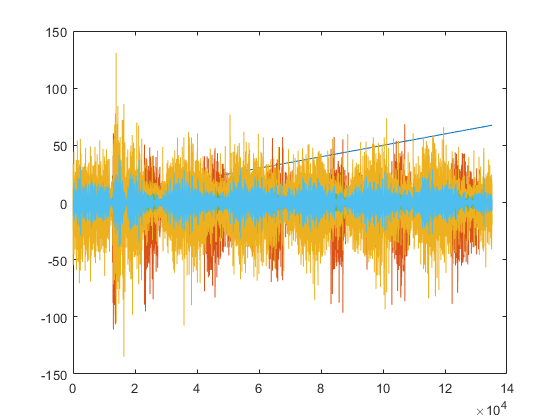


[b,a] = fir1(200,Wn);

sig_filtered = filter(b, a, signal);
figure, plot(signal), hold on, plot(sig_filtered);

*Obiettivo 2: Normalizzazione del segnale EMG rispetto al massimo valore di ogni soggetto. *

%uso funzione data_normalization()
[sample1_muscle1_norm,sample1_muscle2_norm]=data_normalization(emg_data(:,1)); 
[sample2_muscle1_norm,sample2_muscle2_norm]=data_normalization(emg_data(:,2));
[sample3_muscle1_norm,sample3_muscle2_norm]=data_normalization(emg_data(:,3));

*Obiettivo 3: Calcolare lo spettro medio per ogni soggetto per ogni muscolo.*

%muscle1=cell2mat(emg_data(1,1))

muscle1 = 135187×3 single matrix
         0   -3.6255   13.7970
    0.0005   -4.6326   19.7388
    0.0010   -4.1290   25.6805
    0.0015   -0.1007   31.3202
    0.0020   -7.0496   23.0621
    0.0025   -8.3588    3.7262
    0.0030   -1.4099   -1.9135
    0.0035   -2.3163  -15.3076
    0.0040   -5.1361  -17.7246
    0.0045   -2.5177  -23.2635


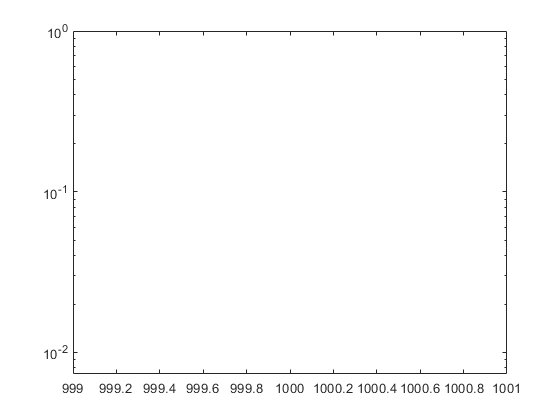

%psd=zeros(floor(nfft/2)+1, length(muscle1(:,1)));
overlap=100;
window=200;
functionpsd(emg_data(:,1), overlap, window, nfft, 1000);



data=emg_data(:, 1);
for index=1 : 1 : 8
    data_matrix=cell2mat(data(index,1));
    if index==1
        vector_muscle1=[data_matrix(:,2)];
        vector_muscle2=[data_matrix(:,3)];
        
    end
    if index>1
        vector_muscle1=[vector_muscle1;data_matrix(:,2)];
        vector_muscle2=[vector_muscle2;data_matrix(:,3)];
        
    end
end 
[psd_m11, ~]=pwelch(vector_muscle1', window, overlap, nfft, fs);
[psd_m12, ~]=pwelch(vector_muscle2', window, overlap, nfft, fs);

meanpsd_m11=mean(psd_m11,2);
meanpsd_m12=mean(psd_m12,2);

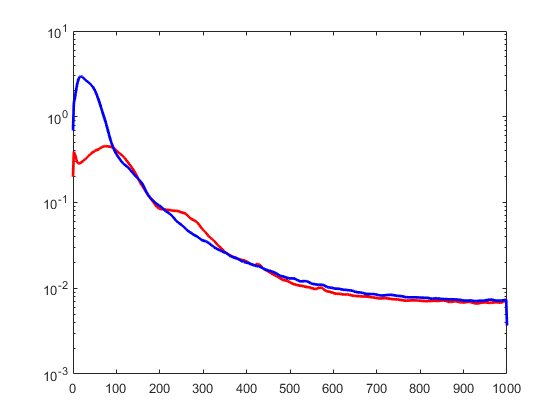


figure
semilogy(f, meanpsd_m11 ,  'Color' , 'r', 'LineWidth', 2) 
hold on 
semilogy(f, meanpsd_m12 ,  'Color' , 'b', 'LineWidth', 2) 

*Obiettivo 4: Trovare le attivazioni per ogni soggetto e per ogni prova.*

%uso funzione detect_activation()

*Obiettivo 5: Visualizzazione delle singole attivazioni nelle 4 condizioni.*

...

*Obiettivo 6: calcolare e visualizzare la durata di attivazione media per ogni soggetto e per ogni prova.*

uso full_width at half maximum

...

*Obiettivo 7: Effettuare un permutation test sui dati tramite l'utilizzo di una funzione.*

%uso funzione my_permutation_test()